wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload = classicload(:);
fenshijijia = fenshijijia(:);
n = numel(wind_vectors{1});

% 目标：最大化 sum(t) = 最小化 -sum(t)，线性规划，使用 linprog
opts = optimoptions('linprog', 'Display', 'iter');
f  = -ones(n, 1);
lb = 0.1 * ones(n, 1);

problem4_results = struct([]);
result_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('\n==================== 情况 %02d：%s + %s ====================\n', ...
                (wind_idx - 1)*numel(sun_vectors) + sun_idx, wind_name, sun_name);

        % 约束 load <= generate：t*41.5 <= wind*40+sun*64 - classicload*6
        % 等价于收紧各时段上界
        ub = min(ones(n,1), (wind*40 + sun*64 - classicload*6) / (20.75*2));

        if any(ub < lb)
            warning('%s + %s：部分时段发电量不足以支撑最低制氢负荷，跳过。', wind_name, sun_name);
            continue;
        end

        t_opt = linprog(f, [], [], [], [], lb, ub, opts);
        t_opt = t_opt(:);
        sum_t = sum(t_opt);
        fprintf('最大 sum(t) = %.6g\n', sum_t);
        disp('最优 t 向量：'); disp(t_opt);

        metrics = calcMetrics(t_opt, classicload, wind, sun, fenshijijia);

        fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', metrics.xnyzf);
        fprintf('总用电量中绿电占比 = %.6g\n', metrics.zydl);
        fprintf('新能源上网电量比例 = %.6g\n', metrics.xnysw);

        J = objFun(t_opt, classicload, wind, sun, fenshijijia);
        fprintf('目标函数 J = %.6g\n', J);

        result_idx = result_idx + 1;
        problem4_results(result_idx).case_idx    = result_idx;
        problem4_results(result_idx).wind_idx    = wind_idx;
        problem4_results(result_idx).wind_name   = wind_name;
        problem4_results(result_idx).sun_idx     = sun_idx;
        problem4_results(result_idx).sun_name    = sun_name;
        problem4_results(result_idx).t_opt       = t_opt;
        problem4_results(result_idx).sum_t       = sum_t;
        problem4_results(result_idx).nh3load     = metrics.nh3load;
        problem4_results(result_idx).load        = metrics.load;
        problem4_results(result_idx).generate    = metrics.generate;
        problem4_results(result_idx).buy         = metrics.buy;
        problem4_results(result_idx).sell        = metrics.sell;
        problem4_results(result_idx).buycost     = metrics.buycost;
        problem4_results(result_idx).dayload     = metrics.dayload;
        problem4_results(result_idx).daygenerate = metrics.daygenerate;
        problem4_results(result_idx).daybuy      = metrics.daybuy;
        problem4_results(result_idx).daysell     = metrics.daysell;
        problem4_results(result_idx).xnyzf       = metrics.xnyzf;
        problem4_results(result_idx).zydl        = metrics.zydl;
        problem4_results(result_idx).xnysw       = metrics.xnysw;
    end
end


==================== 情况 01：wind1 + sun1 ====================



==================== 情况 02：wind1 + sun2 ====================



==================== 情况 03：wind1 + sun3 ====================



==================== 情况 04：wind1 + sun4 ====================



==================== 情况 05：wind2 + sun1 ====================



==================== 情况 06：wind2 + sun2 ====================



==================== 情况 07：wind2 + sun3 ====================



==================== 情况 08：wind2 + sun4 ====================



==================== 情况 09：wind3 + sun1 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.4307272289e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 14.3073


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.6123
    0.8431
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8079
    0.5075
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



新能源自发自用电量占总可用发电量比例 = 0.676328


总用电量中绿电占比 = 1


新能源上网电量比例 = 0.161836


目标函数 J = 3004.42



==================== 情况 10：wind3 + sun2 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.1032134940e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 11.0321


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.2731
    0.3034
    0.4237
    0.6177
    0.7143
    0.8858
    1.0000
    1.0000
    0.9391
    0.8755
    0.7030
    0.4532
    0.3070
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



新能源自发自用电量占总可用发电量比例 = 0.98573


总用电量中绿电占比 = 1


新能源上网电量比例 = 0.00713487


目标函数 J = 3864.13



==================== 情况 11：wind3 + sun3 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 5e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -7.1277108434e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 7.12771


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.2731
    0.2571
    0.2386
    0.3093
    0.2979
    0.4077
    0.4779
    0.5324
    0.4456
    0.4282
    0.3637
    0.2990
    0.2608
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 1


新能源上网电量比例 = 7.47373e-18


目标函数 J = 4202.94



==================== 情况 12：wind3 + sun4 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 4e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -5.5701204819e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 5.57012


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.2731
    0.2263
    0.1615
    0.1859
    0.1129
    0.1610
    0.2620
    0.3782
    0.2914
    0.2894
    0.2403
    0.2219
    0.2299
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 1


新能源上网电量比例 = 9.12887e-18


目标函数 J = 4447.69



==================== 情况 13：wind4 + sun1 ====================



==================== 情况 14：wind4 + sun2 ====================



==================== 情况 15：wind4 + sun3 ====================



==================== 情况 16：wind4 + sun4 ====================



==================== 情况 17：wind5 + sun1 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.4459175904e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 14.4592


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.7092
    0.7677
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7121
    0.4044
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



新能源自发自用电量占总可用发电量比例 = 0.612789


总用电量中绿电占比 = 1


新能源上网电量比例 = 0.193605


目标函数 J = 2842.6



==================== 情况 18：wind5 + sun2 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.1814207229e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 11.8142


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.3699
    0.2279
    0.7035
    0.8349
    0.8876
    1.0000
    1.0000
    1.0000
    0.8826
    0.7310
    0.7497
    0.3574
    0.2039
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



新能源自发自用电量占总可用发电量比例 = 0.964874


总用电量中绿电占比 = 1


新能源上网电量比例 = 0.017563


目标函数 J = 3816.71



==================== 情况 19：wind5 + sun3 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 6e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -8.0573493976e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 8.05735


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.3699
    0.1816
    0.5184
    0.5265
    0.4712
    0.5289
    0.5677
    0.5832
    0.3891
    0.2838
    0.4105
    0.2032
    0.1576
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 1


新能源上网电量比例 = 2.69758e-17


目标函数 J = 4149.83



==================== 情况 20：wind5 + sun4 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 4e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -6.4997590361e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 6.49976


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.3699
    0.1508
    0.4413
    0.4031
    0.2862
    0.2821
    0.3518
    0.4290
    0.2348
    0.1450
    0.2871
    0.1261
    0.1268
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 1


新能源上网电量比例 = 2.15016e-17


目标函数 J = 4346.86



==================== 情况 21：wind6 + sun1 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.3595513253e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 13.5955


最优 t 向量：
    0.1947
    0.2266
    0.2648
    0.2533
    0.2405
    0.2249
    0.5379
    0.7848
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8720
    0.7130
    0.4751
    0.1803
    0.1198
    0.1627
    0.1477
    0.1974



新能源自发自用电量占总可用发电量比例 = 0.74621


总用电量中绿电占比 = 1


新能源上网电量比例 = 0.126895


目标函数 J = 3164.37



==================== 情况 22：wind6 + sun2 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -9.5537349398e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 9.55373


最优 t 向量：
    0.1947
    0.2266
    0.2648
    0.2533
    0.2405
    0.2249
    0.1986
    0.2451
    0.3986
    0.4980
    0.6477
    0.8077
    0.9424
    0.9686
    0.8145
    0.6542
    0.5327
    0.3583
    0.2747
    0.1803
    0.1198
    0.1627
    0.1477
    0.1974



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 1


新能源上网电量比例 = 3.88529e-18


目标函数 J = 3912.56



==================== 情况 23：wind6 + sun3 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 4e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -5.5595180723e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 5.55952


最优 t 向量：
    0.1947
    0.2266
    0.2648
    0.2533
    0.2405
    0.2249
    0.1986
    0.1988
    0.2135
    0.1896
    0.2313
    0.3296
    0.4180
    0.4135
    0.3210
    0.2069
    0.1934
    0.2041
    0.2284
    0.1803
    0.1198
    0.1627
    0.1477
    0.1974



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 1


新能源上网电量比例 = 1.82853e-17


目标函数 J = 4332.77



==================== 情况 24：wind6 + sun4 ====================


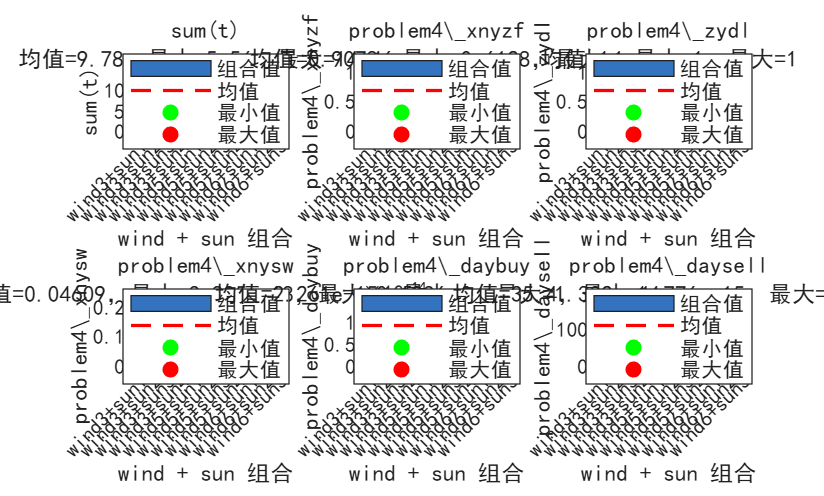


plotProblem4Distributions(problem4_results);


% -------------------------------------------------------------------------
% 风光最小装机容量分析
% -------------------------------------------------------------------------
fprintf('\n\n==================== 风光最小装机容量分析 ====================\n');



==================== 风光最小装机容量分析 ====================


capacity_results = struct([]);
cap_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};
    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        [Cw_min, Cs_min] = calcMinCapacity(wind, sun, classicload);

        cap_idx = cap_idx + 1;
        capacity_results(cap_idx).wind_name = wind_name;
        capacity_results(cap_idx).sun_name  = sun_name;
        capacity_results(cap_idx).wind_idx  = wind_idx;
        capacity_results(cap_idx).sun_idx   = sun_idx;
        capacity_results(cap_idx).Cw_min    = Cw_min;
        capacity_results(cap_idx).Cs_min    = Cs_min;

        fprintf('%-8s + %-6s：最小风电装机 Cw = %.4g MW，最小光电装机 Cs = %.4g MW\n', ...
                wind_name, sun_name, Cw_min, Cs_min);
    end
end

wind1    + sun1  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind1    + sun2  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind1    + sun3  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind1    + sun4  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind2    + sun1  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind2    + sun2  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind2    + sun3  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind2    + sun4  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind3    + sun1  ：最小风电装机 Cw = 36.98 MW，最小光电装机 Cs = 0.1592 MW
wind3    + sun2  ：最小风电装机 Cw = 36.98 MW，最小光电装机 Cs = 0.3348 MW
wind3    + sun3  ：最小风电装机 Cw = 37.57 MW，最小光电装机 Cs = 0 MW
wind3    + sun4  ：最小风电装机 Cw = 37.57 MW，最小光电装机 Cs = 0 MW
wind4    + sun1  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind4    + sun2  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind4    + sun3  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind4    + sun4  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind5    + sun1  ：最小风电装机 Cw = 36.81 MW，最小光电装机 Cs = 0.2212 MW
wind5    + sun2  ：最小风电装机 Cw = 36.81 MW，最小

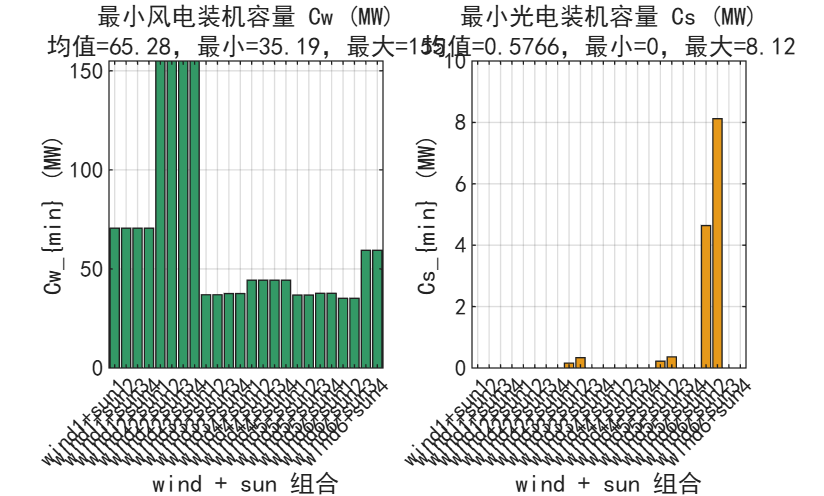


plotMinCapacity(capacity_results);


% -------------------------------------------------------------------------
function J = objFun(t, classicload, wind, sun, fenshijijia)
    t = t(:);
    classicload = classicload(:);
    wind = wind(:);
    sun = sun(:);
    fenshijijia = fenshijijia(:);

    problem4_nh3load = t*20.75*2;
    problem4_load = classicload*6 + problem4_nh3load;
    problem4_generate = wind*40 + sun*64;
    problem4_buy = problem4_load - problem4_generate;
    problem4_sell = problem4_buy;
    problem4_buy(problem4_buy<0) = 0;
    problem4_sell(problem4_sell>0) = 0;
    problem4_buycost = sum(problem4_buy .* fenshijijia);
    problem4_sellcost = sum(problem4_sell*377.9);
    problem4_cost =   problem4_sellcost + problem4_buycost ...
                  + 0.75*2*sum(t)*2 ...
                  + 1.5*2*1000*0.2*60000/365/30 ...
                  + 10*2*sum(t)*100 ...
                  + 10*2*sum(t)*150 ...
                  + sum(sun)*64*1000*0.12 ...
                  + sum(wind)*40*1000*0.15;
    J = problem4_cost / (sum(t)*3);
end

% -------------------------------------------------------------------------
function metrics = calcMetrics(t, classicload, wind, sun, fenshijijia)
    t = t(:); classicload = classicload(:);
    wind = wind(:); sun = sun(:); fenshijijia = fenshijijia(:);

    metrics.nh3load  = t * 20.75 * 2;
    metrics.load     = classicload * 6 + metrics.nh3load;
    metrics.generate = wind * 40 + sun * 64;

    diff = metrics.load - metrics.generate;
    metrics.buy  = diff; metrics.sell = diff;
    metrics.buy(metrics.buy < 0)   = 0;
    metrics.sell(metrics.sell > 0) = 0;

    metrics.buycost     = sum(metrics.buy .* fenshijijia);
    metrics.dayload     = sum(metrics.load);
    metrics.daygenerate = sum(metrics.generate);
    metrics.daybuy      = sum(metrics.buy);
    metrics.daysell     = abs(sum(metrics.sell));

    metrics.xnyzf = (metrics.dayload - metrics.daysell - metrics.daybuy) / metrics.daygenerate;
    metrics.zydl  = (metrics.daygenerate - metrics.daysell) / metrics.dayload;
    metrics.xnysw = metrics.daysell / metrics.daygenerate;
end

% -------------------------------------------------------------------------
function plotProblem4Distributions(problem4_results)
    if isempty(problem4_results)
        warning('没有可绘制的结果。');
        return;
    end

    sort_keys = [[problem4_results.wind_idx]', [problem4_results.sun_idx]'];
    [~, order] = sortrows(sort_keys, [1 2]);
    problem4_results = problem4_results(order);

    combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                            problem4_results, 'UniformOutput', false);

    metric_fields = {'sum_t', 'xnyzf', 'zydl', 'xnysw', 'daybuy', 'daysell'};
    metric_names  = {'sum(t)', 'problem4\_xnyzf', 'problem4\_zydl', ...
                     'problem4\_xnysw', 'problem4\_daybuy', 'problem4\_daysell'};

    figure('Name', 'problem4：各 wind/sun 组合指标分布', 'Color', 'w');

    for metric_idx = 1:numel(metric_fields)
        metric_field = metric_fields{metric_idx};
        metric_name  = metric_names{metric_idx};
        values = arrayfun(@(r) r.(metric_field), problem4_results);

        subplot(2, 3, metric_idx);
        bar(values, 'FaceColor', [0.2 0.45 0.75]);
        grid on; hold on;

        valid_values = values(~isnan(values));
        mean_value = mean(valid_values);
        min_value  = min(valid_values);
        max_value  = max(valid_values);
        [~, min_idx] = min(values);
        [~, max_idx] = max(values);

        plot(xlim, [mean_value mean_value], 'r--', 'LineWidth', 1.2);
        scatter(min_idx, min_value, 45, 'g', 'filled');
        scatter(max_idx, max_value, 45, 'r', 'filled');

        title({metric_name, sprintf('均值=%.4g，最小=%.4g，最大=%.4g', ...
               mean_value, min_value, max_value)}, 'Interpreter', 'none');
        xlabel('wind + sun 组合');
        ylabel(metric_name, 'Interpreter', 'none');
        set(gca, 'XTick', 1:numel(combo_labels), ...
                 'XTickLabel', combo_labels, 'XTickLabelRotation', 45);
        xlim([0.5, numel(combo_labels) + 0.5]);

        if min_value == max_value
            ylim([min_value - 0.5, max_value + 0.5]);
        end

        legend({'组合值', '均值', '最小值', '最大值'}, 'Location', 'best', 'FontSize', 8);
        hold off;
    end
end

% -------------------------------------------------------------------------
function [Cw_min, Cs_min] = calcMinCapacity(wind, sun, classicload)
    % 求最小风电(Cw)和光电(Cs)装机容量，使所有时段满足 ub >= lb=0.1
    % 即：wind_i*Cw + sun_i*Cs >= classicload_i*6 + 0.1*20.75*2  for all i
    % 目标：最小化 Cw + Cs
    wind = wind(:); sun = sun(:); classicload = classicload(:);
    rhs = classicload * 6 + 0.1 * 20.75 * 2;

    % linprog: min f'x  s.t. A*x<=b, x>=lb
    % 变量 x = [Cw; Cs]
    f_cap  = [1; 1];
    A_cap  = -[wind, sun];   % -wind*Cw - sun*Cs <= -rhs
    b_cap  = -rhs;
    lb_cap = [0; 0];

    opts_cap = optimoptions('linprog', 'Display', 'off');
    [x_opt, ~, exitflag] = linprog(f_cap, A_cap, b_cap, [], [], lb_cap, [], opts_cap);

    if exitflag == 1
        Cw_min = x_opt(1);
        Cs_min = x_opt(2);
    else
        Cw_min = NaN;
        Cs_min = NaN;
        warning('calcMinCapacity：线性规划无可行解，exitflag=%d。', exitflag);
    end
end

% -------------------------------------------------------------------------
function plotMinCapacity(capacity_results)
    if isempty(capacity_results)
        warning('没有可绘制的装机容量结果。');
        return;
    end

    sort_keys = [[capacity_results.wind_idx]', [capacity_results.sun_idx]'];
    [~, order] = sortrows(sort_keys, [1 2]);
    capacity_results = capacity_results(order);

    combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                            capacity_results, 'UniformOutput', false);
    Cw_vals = [capacity_results.Cw_min];
    Cs_vals = [capacity_results.Cs_min];

    figure('Name', 'problem4：最小风光装机容量', 'Color', 'w');

    subplot(1, 2, 1);
    bar(Cw_vals, 'FaceColor', [0.2 0.6 0.4]);
    grid on;
    title(sprintf('最小风电装机容量 Cw (MW)\n均值=%.4g，最小=%.4g，最大=%.4g', ...
          mean(Cw_vals(~isnan(Cw_vals))), min(Cw_vals), max(Cw_vals)), 'Interpreter', 'none');
    xlabel('wind + sun 组合');
    ylabel('Cw_{min} (MW)', 'Interpreter', 'none');
    set(gca, 'XTick', 1:numel(combo_labels), 'XTickLabel', combo_labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(combo_labels) + 0.5]);

    subplot(1, 2, 2);
    bar(Cs_vals, 'FaceColor', [0.9 0.6 0.1]);
    grid on;
    title(sprintf('最小光电装机容量 Cs (MW)\n均值=%.4g，最小=%.4g，最大=%.4g', ...
          mean(Cs_vals(~isnan(Cs_vals))), min(Cs_vals), max(Cs_vals)), 'Interpreter', 'none');
    xlabel('wind + sun 组合');
    ylabel('Cs_{min} (MW)', 'Interpreter', 'none');
    set(gca, 'XTick', 1:numel(combo_labels), 'XTickLabel', combo_labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(combo_labels) + 0.5]);
end

fprintf('\n\n==================== 能源自给与风光利用状况分析 ====================\n');



==================== 能源自给与风光利用状况分析 ====================



% -------------------------------------------------------------------------
% 1. 计算各场景的关键比例指标（无储能联网工况）
% -------------------------------------------------------------------------
n_case = numel(problem4_results);
self_sufficiency = zeros(1, n_case);   % 能源自给率 = 1 - daybuy/dayload
re_utilization   = zeros(1, n_case);   % 风光利用率 = 1 - daysell/daygenerate
curtailment_rate = zeros(1, n_case);   % 弃风弃光率 = daysell/daygenerate
buy_ratio        = zeros(1, n_case);   % 网购电量占负荷比
combo_labels     = cell(1, n_case);

for k = 1:n_case
    r = problem4_results(k);
    self_sufficiency(k) = 1 - r.daybuy / r.dayload;
    re_utilization(k)   = 1 - r.daysell / r.daygenerate;
    curtailment_rate(k) = r.daysell / r.daygenerate;
    buy_ratio(k)        = r.daybuy / r.dayload;
    combo_labels{k}     = sprintf('%s+%s', r.wind_name, r.sun_name);
end

% 打印统计表
fprintf('%-14s | %-10s | %-10s | %-10s | %-10s\n', ...
        '场景', '自给率(%)', '利用率(%)', '弃电率(%)', '购电占比(%)');

场景             | 自给率(%)     | 利用率(%)     | 弃电率(%)     | 购电占比(%)   


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


for k = 1:n_case
    fprintf('%-14s | %9.2f  | %9.2f  | %9.2f  | %9.2f\n', ...
            combo_labels{k}, self_sufficiency(k)*100, re_utilization(k)*100, ...
            curtailment_rate(k)*100, buy_ratio(k)*100);
end

wind3+sun1     |    100.00  |     83.82  |     16.18  |      0.00
wind3+sun2     |    100.00  |     99.29  |      0.71  |      0.00
wind3+sun3     |    100.00  |    100.00  |      0.00  |      0.00
wind3+sun4     |    100.00  |    100.00  |      0.00  |      0.00
wind5+sun1     |    100.00  |     80.64  |     19.36  |      0.00
wind5+sun2     |    100.00  |     98.24  |      1.76  |      0.00
wind5+sun3     |    100.00  |    100.00  |      0.00  |      0.00
wind5+sun4     |    100.00  |    100.00  |      0.00  |      0.00
wind6+sun1     |    100.00  |     87.31  |     12.69  |      0.00
wind6+sun2     |    100.00  |    100.00  |      0.00  |      0.00
wind6+sun3     |    100.00  |    100.00  |      0.00  |      0.00


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


fprintf('%-14s | %9.2f  | %9.2f  | %9.2f  | %9.2f\n', '均值', ...
        mean(self_sufficiency)*100, mean(re_utilization)*100, ...
        mean(curtailment_rate)*100, mean(buy_ratio)*100);

均值             |    100.00  |     95.39  |      4.61  |      0.00



% -------------------------------------------------------------------------
% 2. 全场景鲁棒最小风光装机容量
%    对所有 24 个场景的每个时段都要求：wind_i*Cw + sun_i*Cs >= classicload*6 + 0.1*20.75*2
%    决策变量 x = [Cw; Cs]，目标 min Cw + Cs
% -------------------------------------------------------------------------
fprintf('\n---------- 全场景鲁棒最小装机容量 ----------\n');


---------- 全场景鲁棒最小装机容量 ----------



A_robust  = [];
b_robust  = [];
rhs_const = classicload * 6 + 0.1 * 20.75 * 2;   % 各时段最低需求 (MW)

for wi = 1:numel(wind_vectors)
    for si = 1:numel(sun_vectors)
        wind_i = wind_vectors{wi};
        sun_i  = sun_vectors{si};
        A_robust = [A_robust; -[wind_i, sun_i]];   %#ok<AGROW>
        b_robust = [b_robust; -rhs_const];         %#ok<AGROW>
    end
end

f_robust  = [1; 1];
lb_robust = [0; 0];
opts_r    = optimoptions('linprog', 'Display', 'off');
[x_robust, ~, flag_r] = linprog(f_robust, A_robust, b_robust, [], [], lb_robust, [], opts_r);

if flag_r == 1
    Cw_robust = x_robust(1);
    Cs_robust = x_robust(2);
    fprintf('鲁棒最小风电装机 Cw* = %.4f MW\n', Cw_robust);
    fprintf('鲁棒最小光电装机 Cs* = %.4f MW\n', Cs_robust);
    fprintf('合计装机 Cw* + Cs*   = %.4f MW\n', Cw_robust + Cs_robust);
    fprintf('（保证 24 个风光场景的所有时段均不缺电）\n');
else
    Cw_robust = NaN; Cs_robust = NaN;
    warning('鲁棒最小装机求解失败，exitflag=%d', flag_r);
end

鲁棒最小风电装机 Cw* = 154.9651 MW


鲁棒最小光电装机 Cs* = 0.0000 MW


合计装机 Cw* + Cs*   = 154.9651 MW


（保证 24 个风光场景的所有时段均不缺电）


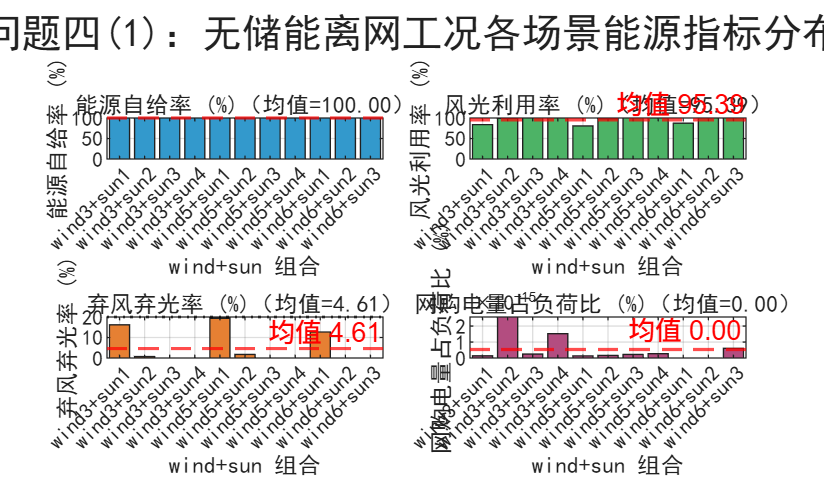


% -------------------------------------------------------------------------
% 3. 可视化：自给率/利用率/弃电率/购电占比 四指标柱状图
% -------------------------------------------------------------------------
figure('Name', 'problem4-1：能源指标分场景对比', 'Color', 'w', ...
       'Position', [80 80 1100 650]);

metric_data   = {self_sufficiency*100, re_utilization*100, ...
                 curtailment_rate*100, buy_ratio*100};
metric_titles = {'能源自给率 (%)', '风光利用率 (%)', ...
                 '弃风弃光率 (%)', '网购电量占负荷比 (%)'};
metric_colors = {[0.2 0.6 0.8], [0.3 0.7 0.4], ...
                 [0.9 0.5 0.2], [0.7 0.3 0.5]};
% 政策红线（仅自给率 60% / 利用率 ≥ 80% 即弃电 ≤ 20% 有红线，其余仅参考）
ref_lines = {[], [], 20, []};

for mi = 1:4
    subplot(2, 2, mi);
    bar(metric_data{mi}, 'FaceColor', metric_colors{mi}); grid on; hold on;
    yline(mean(metric_data{mi}), 'r--', 'LineWidth', 1.2, ...
          'Label', sprintf('均值 %.2f', mean(metric_data{mi})));
    if ~isempty(ref_lines{mi})
        yline(ref_lines{mi}, 'k:', 'LineWidth', 1.0, ...
              'Label', sprintf('政策线 %.0f%%', ref_lines{mi}));
    end
    title(sprintf('%s（均值=%.2f）', metric_titles{mi}, mean(metric_data{mi})), ...
          'Interpreter', 'none');
    xlabel('wind+sun 组合'); ylabel(metric_titles{mi});
    set(gca, 'XTick', 1:n_case, 'XTickLabel', combo_labels, 'XTickLabelRotation', 45);
    xlim([0.5, n_case+0.5]);
end
sgtitle('问题四(1)：无储能离网工况各场景能源指标分布');

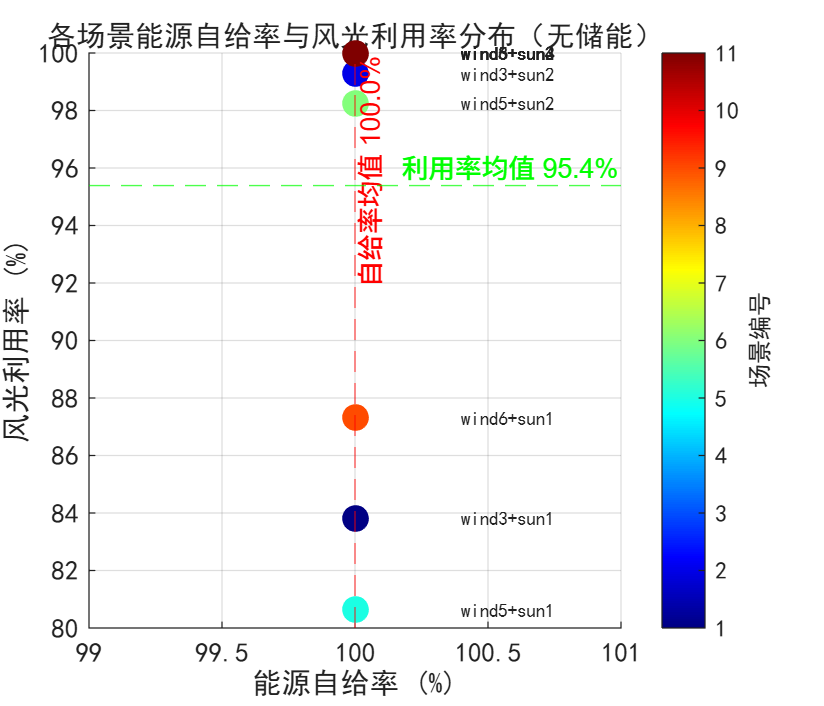


% -------------------------------------------------------------------------
% 4. 自给率 vs 利用率 散点图（场景定位）
% -------------------------------------------------------------------------
figure('Name', 'problem4-1：能源自给 vs 风光利用', 'Color', 'w', ...
       'Position', [150 150 700 600]);
scatter(self_sufficiency*100, re_utilization*100, 100, 1:n_case, 'filled');
colormap(jet); cb = colorbar; cb.Label.String = '场景编号';
xlabel('能源自给率 (%)'); ylabel('风光利用率 (%)');
title('各场景能源自给率与风光利用率分布（无储能）');
grid on; hold on;

% 标注每个点
for k = 1:n_case
    text(self_sufficiency(k)*100 + 0.4, re_utilization(k)*100, ...
         combo_labels{k}, 'FontSize', 7, 'Interpreter', 'none');
end

% 均值参考线
xline(mean(self_sufficiency)*100, 'r--', sprintf('自给率均值 %.1f%%', mean(self_sufficiency)*100));
yline(mean(re_utilization)*100,   'g--', sprintf('利用率均值 %.1f%%', mean(re_utilization)*100));

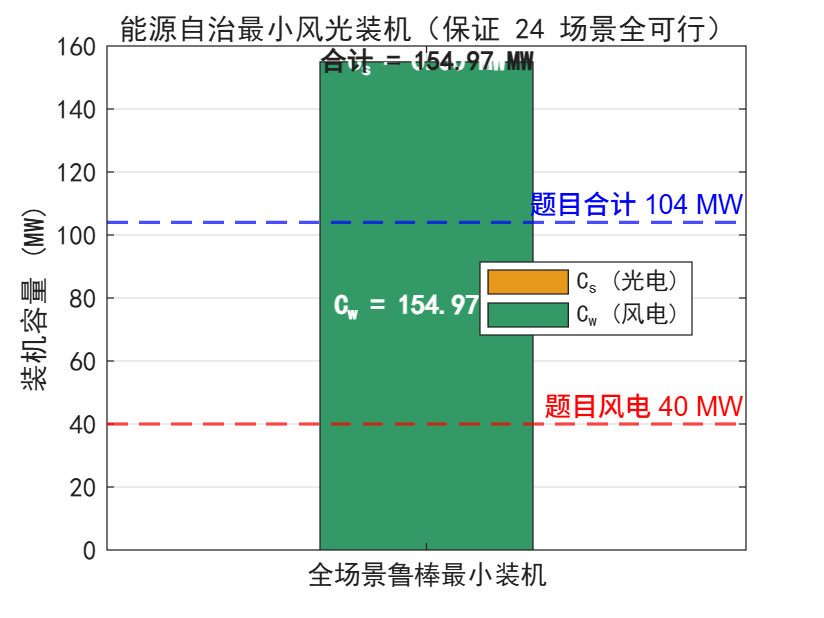


% -------------------------------------------------------------------------
% 5. 鲁棒装机容量单独可视化（含构成）
% -------------------------------------------------------------------------
figure('Name', 'problem4-1：全场景鲁棒最小装机', 'Color', 'w', ...
       'Position', [200 200 600 450]);
if ~isnan(Cw_robust)
    hb = bar(1, [Cw_robust, Cs_robust], 'stacked'); grid on; hold on;
    hb(1).FaceColor = [0.2 0.6 0.4];
    hb(2).FaceColor = [0.9 0.6 0.1];
    
    % 标注数值
    text(1, Cw_robust/2, sprintf('C_w = %.2f MW', Cw_robust), ...
         'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold');
    text(1, Cw_robust + Cs_robust/2, sprintf('C_s = %.2f MW', Cs_robust), ...
         'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold');
    text(1, Cw_robust + Cs_robust + 0.5, sprintf('合计 = %.2f MW', Cw_robust + Cs_robust), ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    
    % 与题目给定装机对比
    yline(40, 'r--', '题目风电 40 MW', 'LineWidth', 1.2);
    yline(40 + 64, 'b--', '题目合计 104 MW', 'LineWidth', 1.2);
    
    set(gca, 'XTick', 1, 'XTickLabel', {'全场景鲁棒最小装机'});
    ylabel('装机容量 (MW)');
    legend({'C_w (风电)', 'C_s (光电)'}, 'Location', 'best');
    title('能源自治最小风光装机（保证 24 场景全可行）');
end


% -------------------------------------------------------------------------
% 6. 保存到 base workspace，供 problem4_2 对比
% -------------------------------------------------------------------------
problem4_1_summary.self_sufficiency = self_sufficiency;
problem4_1_summary.re_utilization   = re_utilization;
problem4_1_summary.curtailment_rate = curtailment_rate;
problem4_1_summary.buy_ratio        = buy_ratio;
problem4_1_summary.combo_labels     = {combo_labels{:}};
problem4_1_summary.Cw_robust        = Cw_robust;
problem4_1_summary.Cs_robust        = Cs_robust;

assignin('base', 'problem4_1_summary', problem4_1_summary);
fprintf('\nproblem4_1_summary 已保存到 workspace，供 problem4_2 对比使用。\n');


problem4_1_summary 已保存到 workspace，供 problem4_2 对比使用。
